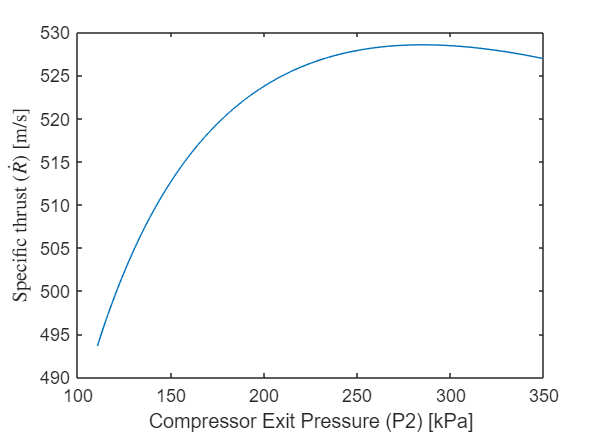

clear;
clc;

% Known
M = 2.1;
Ti = 216;
Pi = 12.11;
Pe = 12.11;
gamma = 1.4;
R = 287;
cp = 1006;

ai = sqrt(gamma*R*Ti);
ui = M*ai;
dT = ui^2/(2*cp);

T1 = dT+Ti;
P1 = Pi*(T1/Ti)^(gamma/(gamma-1));

% Compressor exit
P2 = [P1:1:350];
T2 = T1*(P2./P1).^((gamma-1)/(gamma));

% Combustion chamber exit
P3 = P2;
T3 = 1313;

% Turbine exit
T4 = T3+T1-T2;
P4 = P3.*(T4/T3).^(gamma/(gamma-1));

% Not using afterburner
P5 = P4;
T5 = T4;

% Nozzle exit
Te = T5.*(Pe./P5).^((gamma-1)/gamma);
ue = sqrt(2*cp*(abs(T5-Te)));

% Thrust
R_sp = ue-ui;

plot(P2,R_sp)
xlabel('Compressor Exit Pressure (P2) [kPa]')
ylabel('Specific thrust ($\dot{R}$) [m/s]', 'Interpreter','latex')


% Find optimal r
i = find(R_sp==max(R_sp));
r = P2(i)/P1

r = 2.5841

R_sp(i)

ans = 528.5600